# Winner-take-all in reduced system

clear;
clc;
addpath('../funcs');

load ../../data/reducedL46_onlyA_0_0.5_0_0.05_Iattn_0.02.mat

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 60;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 50;
markSZ = 50;

## only attention, green

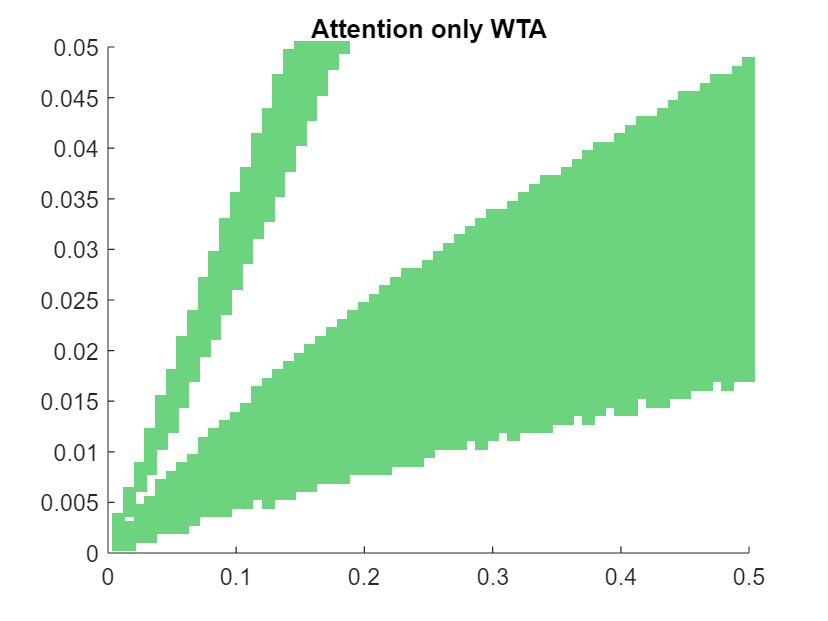

pop = 1;
WTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = envSheet(i,j,pop,1); cond1 = envSheet(i,j,pop,2); cond2 = envSheet(i,j,pop,3);
        cond3 = envSheet(i,j,pop,4); cond4 = envSheet(i,j,pop,5); cond5 = envSheet(i,j,pop,6);
        if cond4>cond5
            WTA(i,j) = 1;

        end
    end
end

WTA = WTA == 1;

figure();
for i = 1:steps
    x = Delta_e(WTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Attention only WTA");

## rule out?

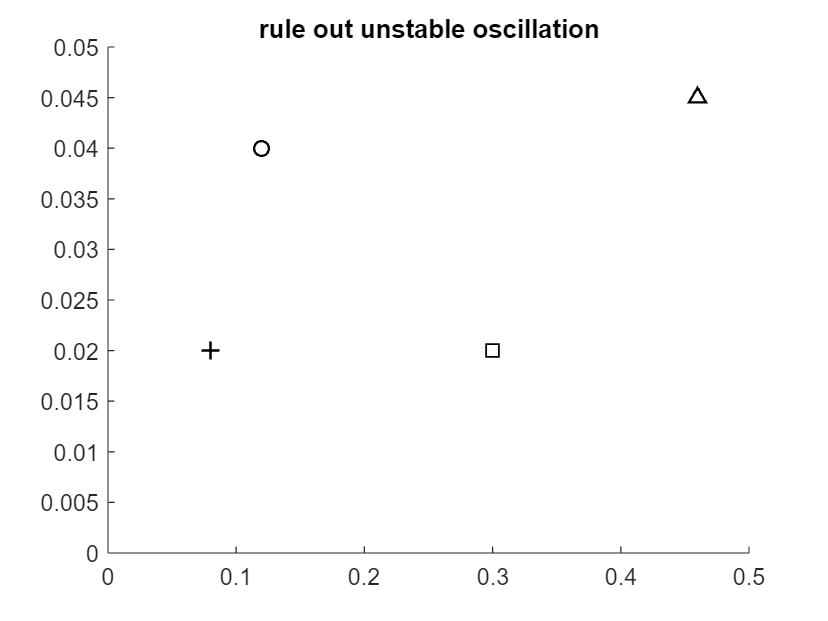

ruleOut = zeros(steps,steps);
maxPks = 5;

for i = 1:steps
    for j = 1:steps
        cond4 = squeeze(psdPeaksSheet(i,j,:,5)); cond5 = squeeze(psdPeaksSheet(i,j,:,6));
        tmp = max([cond4; cond5]);
        if tmp<=maxPks && tmp>=1 
            ruleOut(i,j) = 1;
        end
    end
end

ruleOut = ruleOut == 1;

figure();
for i = 1:steps
    x = Delta_e(ruleOut(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#9E9E9E"); % green
    hold on;
end
scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.08, 0.02, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.3, 0.02, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.46, 0.045, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
title("rule out unstable oscillation");

## add sensory, blue

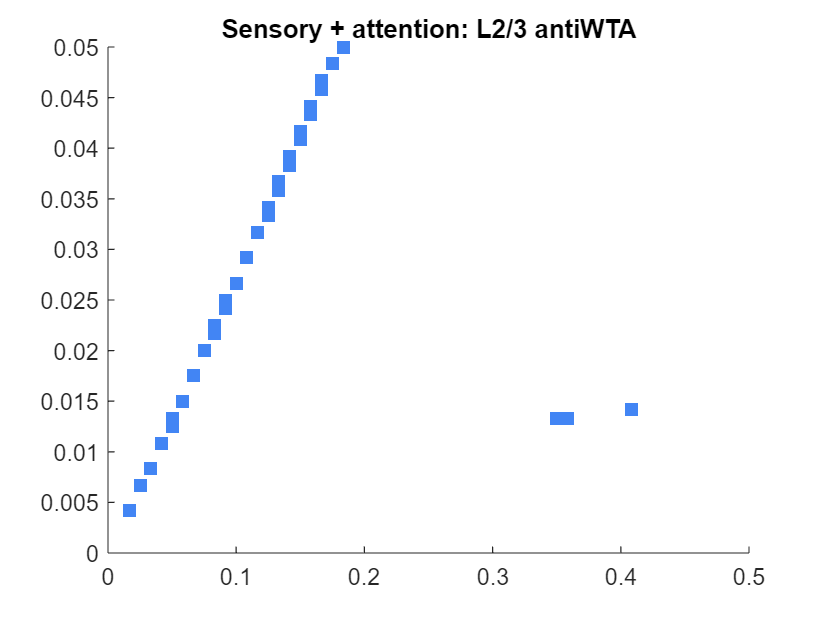

load ../../data/reducedL46_SandA_0_0.5_0_0.05_Iattn_0.02.mat
pop = 1;
antiWTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = envSheet(i,j,pop,1); cond1 = envSheet(i,j,pop,2); cond2 = envSheet(i,j,pop,3);
        cond3 = envSheet(i,j,pop,4); cond4 = envSheet(i,j,pop,5); cond5 = envSheet(i,j,pop,6);
        if cond4<cond5
            antiWTA(i,j) = 1;
        end
    end
end

antiWTA = antiWTA == 1;
antiWTA = and(antiWTA,WTA);

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#4285F4"); % blue
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Sensory + attention: L2/3 antiWTA");

## Sensory + Attention, ordered pattern, yellow

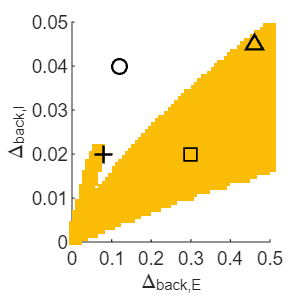

pop = 5;
order = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = envSheet(i,j,pop,1); cond1 = envSheet(i,j,pop,2); cond2 = envSheet(i,j,pop,3);
        cond3 = envSheet(i,j,pop,4); cond4 = envSheet(i,j,pop,5); cond5 = envSheet(i,j,pop,6);
        if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5
            order(i,j) = 1;
        end
    end
end

order = order == 1;
order = and(order,WTA);

figure();
for i = 1:steps
    x = Delta_e(order(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FBBC05"); % yellow
    hold on;
end

scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.08, 0.02, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.3, 0.02, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.46, 0.045, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'scatter_yellow');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');


## Intersection, red

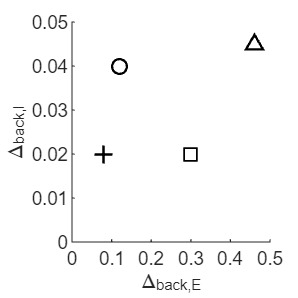

order = and(order,antiWTA);

figure();
for i = 1:steps
    x = Delta_e(order(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#ED5564"); % red
    hold on;
end

scatter(0.12, 0.04, 40,"o",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.08, 0.02, 60,"+",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.3, 0.02, 50,"square",'LineWidth',1,'MarkerEdgeColor','k');
scatter(0.46, 0.045, 40,"^",'LineWidth',1,'MarkerEdgeColor','k');

hold off;
axis([0 0.5 0 0.05]);
xlabel("\Delta_{back,E}");
ylabel("\Delta_{back,I}");
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);

x0 = 0; y0 = 0; width = 4.5; height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'scatter_red');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');